%Test LP solver of three methods with variable number changed from 10 to 200
%Primal-dual interior-point, Primal simplex algorithm and linprog 
%
niparray=[];
nsimarray=[];
nlinparray=[];
itip=[];
itsim=[];
itlinp=[];
fvaliparray=[];
fvalsimarray=[];
fvallinparray=[];
fvalgoal=[];
for i=10:10:200
    %intialization of test problem
    n=i
    m=0.5*n;
    A=randn(m,n);
    x=zeros(n,1);
    x(1:m,1)=abs(rand(m,1))*5;
    lambda=zeros(n,1);
    lambda(m+1:n,1) = abs(rand(n-m,1))*5;
    mu = rand(m,1);
    g = A'*mu + lambda;
    b = A*x;
    fval_goal=g'*x;
    fvalgoal=[fvalgoal fval_goal];
    %Primal-dual interior-point
    [x_ip,output1]=ipLP(g,A,b);
    nip=norm(x-x_ip,2);
    niparray=[niparray nip];
    fvaliparray=[fvaliparray output1.fval];
    itip=[itip output1.iteration];
    %Primal simplex algorithm
    base=m+1:n
    [x_sim,output2]=Pri_Simple(g,A,b,base)
    nsim=norm(x_sim'-x,2);
    nsimarray=[nsimarray nsim];
    fvalsimarray=[fvalsimarray output2.fval];
    itsim=[itsim output2.iteration];
    %linprog 
    options = optimoptions('linprog','Algorithm','dual-simplex');
    [x_lin,fvallinp,exitflag,output3,lambda]=linprog(g,[],[],A,b,zeros(n,1),[],options)
    nlinp=norm(x_lin-x,2)
    nlinparray=[nlinparray nlinp];
    fvallinparray=[fvallinparray fvallinp];
    itlinp=[itlinp output3.iterations];
end

n = 10

base =      6     7     8     9    10


x_sim =     3.2501    1.2025    0.5999    3.3597         0   -0.2749         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 7.3754
    iteration: 5
       xarray: [0 0 0 0 0 -2.7788 -21.6681 39.2524 -1.3294 -18.9641 6.4052 0 0 0 0 -1.3208 1.3244 0 2.3470 0.5124 6.3223 0 0 0 0.5678 -1.2481 1.4422 0 1.5266 0 5.9815 0 0.9465 0 2.2240 -0.8775 3.0909 0 0 0 4.1243 0 0.6645 3.0173 0 -0.7010 0.8583 0 0 0]



Optimal solution found.



x_lin =     3.1271
    2.1250
    0.6335
    2.7325
    0.6559
         0
         0
         0
         0
         0


fvallinp = 7.9315

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 5
    constrviolation: 6.2172e-15
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 4.9960e-16


lambda = 包含以下字段的 struct :
      lower: [10×1 double]
      upper: [10×1 double]
      eqlin: [5×1 double]
    ineqlin: []


nlinp = 7.4086e-15

n = 20

base =     11    12    13    14    15    16    17    18    19    20


x_sim =     0.5494    3.1526    0.0122    1.5979    3.0031    1.9908    0.7407    3.5679    3.2548    4.1866         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 1.1977
    iteration: 13
       xarray: [1×260 double]



Optimal solution found.



x_lin =     0.5494
    3.1526
    0.0122
    1.5979
    3.0031
    1.9908
    0.7407
    3.5679
    3.2548
    4.1866


fvallinp = 1.1977

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 11
    constrviolation: 1.7764e-14
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.7764e-15


lambda = 包含以下字段的 struct :
      lower: [20×1 double]
      upper: [20×1 double]
      eqlin: [10×1 double]
    ineqlin: []


nlinp = 1.7467e-14

n = 30

base =     16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


x_sim =     4.9700    3.4627    0.5890    2.3476    2.5186    4.0961    3.6125    2.8076    3.4823    0.8719    3.2388    3.7419    1.6085    2.3451    4.0841         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -25.5887
    iteration: 18
       xarray: [1×540 double]



Optimal solution found.



x_lin =     4.9700
    3.4627
    0.5890
    2.3476
    2.5186
    4.0961
    3.6125
    2.8076
    3.4823
    0.8719


fvallinp = -25.5887

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 26
    constrviolation: 4.6185e-14
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.0658e-14


lambda = 包含以下字段的 struct :
      lower: [30×1 double]
      upper: [30×1 double]
      eqlin: [15×1 double]
    ineqlin: []


nlinp = 8.2954e-14

n = 40

base =     21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


x_sim =     3.9541    1.8986    1.9553    1.7606    3.1878    4.4180    2.2157    2.8894    0.3902    1.0928    3.1035    0.8576    2.7890    0.7549    4.6144    3.4147    2.3853    4.7054    0.7416    4.4319         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -10.6324
    iteration: 29
       xarray: [1×1160 double]



Optimal solution found.



x_lin =     3.9541
    1.8986
    1.9553
    1.7606
    3.1878
    4.4180
    2.2157
    2.8894
    0.3902
    1.0928


fvallinp = -10.6324

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 25
    constrviolation: 1.9540e-14
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 4.4409e-15


lambda = 包含以下字段的 struct :
      lower: [40×1 double]
      upper: [40×1 double]
      eqlin: [20×1 double]
    ineqlin: []


nlinp = 2.1699e-14

n = 50

base =     26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x_sim =     2.4198    2.8479    4.9324    2.0918    3.8847    1.1416    4.7865    2.8802    4.1516    2.0723    3.7609    4.3463    0.4324    1.7970    2.7982    0.1678    1.8159    1.7121    0.4931    0.2687    3.3294    3.3809    0.0717    4.9454    2.1817         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -25.5475
    iteration: 31
       xarray: [1×1550 double]



Optimal solution found.



x_lin =     2.4198
    2.8479
    4.9324
    2.0918
    3.8847
    1.1416
    4.7865
    2.8802
    4.1516
    2.0723


fvallinp = -25.5475

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 35
    constrviolation: 1.1369e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.3315e-14


lambda = 包含以下字段的 struct :
      lower: [50×1 double]
      upper: [50×1 double]
      eqlin: [25×1 double]
    ineqlin: []


nlinp = 1.0524e-13

n = 60

base =     31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


x_sim =     0.3878    0.9195    3.8990    0.4775    3.1197    0.9288    4.0322    1.9693    1.9534    0.1362    0.4226    2.1758    0.6035    3.4678    3.8459    3.2996    2.4929    0.0340    1.3854    2.1838    4.0982    4.4087    3.5583    0.5480    1.6435    3.2330    3.8344    3.1144    2.9904    4.0180         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -25.8126
    iteration: 61
       xarray: [1×3660 double]



Optimal solution found.



x_lin =     0.3878
    0.9195
    3.8990
    0.4775
    3.1197
    0.9288
    4.0322
    1.9693
    1.9534
    0.1362


fvallinp = -25.8126

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 41
    constrviolation: 1.5610e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.3989e-14


lambda = 包含以下字段的 struct :
      lower: [60×1 double]
      upper: [60×1 double]
      eqlin: [30×1 double]
    ineqlin: []


nlinp = 1.5450e-13

n = 70

base =     36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70


x_sim =     4.2890    4.5235    4.0798    0.3616    3.5151    4.2977    3.5478    0.5787    2.4749    0.6700    1.4361    0.3124    4.7884    2.4742    4.4499    0.5410    2.9179    4.4599    1.8057    3.7867    4.2647    3.3353    4.7931    0.2670    2.6355    1.3877    4.1940    4.5923    2.2060    2.3514    3.3832    4.9658    3.8000    3.5042    1.9387         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 92.8497
    iteration: 57
       xarray: [1×3990 double]



Optimal solution found.



x_lin =     4.2890
    4.5235
    4.0798
    0.3616
    3.5151
    4.2977
    3.5478
    0.5787
    2.4749
    0.6700


fvallinp = 92.8497

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 52
    constrviolation: 1.4611e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 4.1744e-14


lambda = 包含以下字段的 struct :
      lower: [70×1 double]
      upper: [70×1 double]
      eqlin: [35×1 double]
    ineqlin: []


nlinp = 2.1696e-13

n = 80

base =     41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80


x_sim =     0.7030    4.2249    0.7976    3.3216    4.1097    4.7466    1.3825    1.9863    3.4194    2.8182    0.1736    0.3255    4.1700    4.2581    2.9975    4.3498    0.0645    1.6870    4.8738    2.8250    1.4477    4.6316    1.6664    1.9575    4.8689    0.0057    4.1610    1.6051    3.0058    1.2721    0.0603    0.9674    2.8776    1.9733    4.0117    2.9291    1.6661    1.5118    0.7354    4.5015         0         0         0         0         0         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 13.9309
    iteration: 84
       xarray: [1×6720 double]



Optimal solution found.



x_lin =     0.7030
    4.2249
    0.7976
    3.3216
    4.1097
    4.7466
    1.3825
    1.9863
    3.4194
    2.8182


fvallinp = 13.9309

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 79
    constrviolation: 1.5010e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.2204e-14


lambda = 包含以下字段的 struct :
      lower: [80×1 double]
      upper: [80×1 double]
      eqlin: [40×1 double]
    ineqlin: []


nlinp = 8.8445e-14

n = 90

base =     46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90


x_sim =     0.8519    1.0789    1.3086    1.5878    0.8916    1.9099    0.1523    4.5306    2.4855    3.9249    4.0041    2.2880    2.9948    0.4792    3.4332    4.3489    3.7790    4.2768    1.1692    0.0552    2.3174    3.8703    2.9300    1.2194    1.2148    0.1239    0.6678    1.4505    1.3889    0.1232    3.1650    3.2033    0.9533    4.6675    2.0162    1.3427    4.0002    1.0790    4.0523    3.0581    0.7657    1.1303    0.3929    0.0687    0.4292         0         0         0         0         0


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -72.4727
    iteration: 77
       xarray: [1×6930 double]



Optimal solution found.



x_lin =     0.8519
    1.0789
    1.3086
    1.5878
    0.8916
    1.9099
    0.1523
    4.5306
    2.4855
    3.9249


fvallinp = -72.4727

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 69
    constrviolation: 3.0553e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.8422e-14


lambda = 包含以下字段的 struct :
      lower: [90×1 double]
      upper: [90×1 double]
      eqlin: [45×1 double]
    ineqlin: []


nlinp = 5.3118e-13

n = 100

base =     51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100


x_sim =     2.0753    2.1934    1.7953    2.2541    2.2502    4.5358    1.9617    0.9639    0.4301    2.6160    1.6949    4.6611    4.0126    1.4911    1.8670    3.6740    0.3951    4.6061    4.1731    4.4870    3.7103    1.8668    1.3569    2.8467    3.0807    1.6361    2.9885    0.0580    1.4225    3.4106    3.2633    3.0209    2.8049    3.0282    4.9944    4.5824    1.8735    2.2808    4.6649    0.2359    2.7609    1.0653    4.7432    2.9345    4.0350    4.5800    1.5832    2.8096    2.8814    3.7122


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 45.7699
    iteration: 106
       xarray: [1×10600 double]



Optimal solution found.



x_lin =     2.0753
    2.1934
    1.7953
    2.2541
    2.2502
    4.5358
    1.9617
    0.9639
    0.4301
    2.6160


fvallinp = 45.7699

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 81
    constrviolation: 1.3003e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.1591e-13


lambda = 包含以下字段的 struct :
      lower: [100×1 double]
      upper: [100×1 double]
      eqlin: [50×1 double]
    ineqlin: []


nlinp = 1.1479e-12

n = 110

base =     56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105


x_sim =     3.1590    4.0211    2.2866    4.2371    3.0629    4.9011    4.0055    2.9140    3.0708    0.8803    0.9592    3.5561    1.7497    1.9716    1.1205    2.9843    0.6964    1.7265    4.1843    2.8569    4.3595    4.0674    4.5911    2.7965    0.1220    1.8928    1.0997    4.3829    1.2116    1.2280    3.6553    1.9525    1.2215    0.2743    1.9821    3.4117    2.0119    0.7755    3.4662    0.1485    2.2150    2.1050    2.8149    4.2791    3.0479    1.7149    1.6067    2.8461    0.3639    0.3241


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 28.2238
    iteration: 111
       xarray: [1×12210 double]



Optimal solution found.



x_lin =     3.1590
    4.0211
    2.2866
    4.2371
    3.0629
    4.9011
    4.0055
    2.9140
    3.0708
    0.8803


fvallinp = 28.2238

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 117
    constrviolation: 6.2172e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 8.8818e-14


lambda = 包含以下字段的 struct :
      lower: [110×1 double]
      upper: [110×1 double]
      eqlin: [55×1 double]
    ineqlin: []


nlinp = 5.6253e-12

n = 120

base =     61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110


x_sim =     0.4922    0.7301    3.4935    1.3093    2.2186    4.9844    1.4829    1.4645    2.1616    4.0344    3.5029    3.6883    0.2071    0.8692    0.6520    3.6575    2.6778    1.9065    1.8733    3.2140    2.6547    4.8878    4.0005    2.7278    4.3927    1.0846    1.0280    3.6378    2.1116    4.9109    0.6318    1.7241    4.8118    4.9286    1.9259    2.3165    1.5195    2.9075    3.8664    2.5158    2.3848    2.8979    3.4657    1.8534    3.8866    1.0582    1.7834    3.2051    2.6424    3.2952


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -173.1938
    iteration: 144
       xarray: [1×17280 double]



Optimal solution found.



x_lin =     0.4922
    0.7301
    3.4935
    1.3093
    2.2186
    4.9844
    1.4829
    1.4645
    2.1616
    4.0344


fvallinp = -173.1938

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 105
    constrviolation: 9.0949e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 5.0182e-14


lambda = 包含以下字段的 struct :
      lower: [120×1 double]
      upper: [120×1 double]
      eqlin: [60×1 double]
    ineqlin: []


nlinp = 4.3304e-12

n = 130

base =     66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115


x_sim =     3.7871    1.6284    1.0139    0.4016    2.3472    3.5538    0.9511    3.3995    2.0681    4.3029    0.4838    0.4380    4.7198    4.9781    2.8997    3.6784    1.8588    3.2260    2.0772    4.0225    2.7615    3.8506    3.1892    4.8124    0.7951    0.9182    3.1316    0.4145    4.2983    1.4228    3.6641    3.7357    0.0955    4.4542    3.2344    4.6538    4.9345    4.1063    0.5338    4.9246    0.8638    4.1291    3.2614    0.0975    4.1020    2.8688    1.5916    2.5897    0.0178    4.9247


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -328.7353
    iteration: 143
       xarray: [1×18590 double]



Optimal solution found.



x_lin =     3.7871
    1.6284
    1.0139
    0.4016
    2.3472
    3.5538
    0.9511
    3.3995
    2.0681
    4.3029


fvallinp = -328.7353

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 116
    constrviolation: 1.1724e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 6.3949e-14


lambda = 包含以下字段的 struct :
      lower: [130×1 double]
      upper: [130×1 double]
      eqlin: [65×1 double]
    ineqlin: []


nlinp = 1.3944e-12

n = 140

base =     71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120


x_sim =     4.8860    2.6414    3.6133    1.9997    4.5288    3.1830    3.2709    2.6431    2.0502    3.2531    0.5927    4.9468    4.1396    4.5951    1.6139    4.8014    1.7001    3.0427    3.3995    3.7623    4.1351    1.8238    4.5055    1.3791    0.3141    3.7525    4.0583    1.3604    3.4413    3.7015    2.1287    2.7214    1.9656    0.9963    1.0647    1.2298    3.8466    0.5817    4.0904    0.4009    3.8727    3.5260    2.2879    2.3518    3.3290    3.2087    0.7143    2.8867    0.0648    3.9102


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 104.2359
    iteration: 152
       xarray: [1×21280 double]



Optimal solution found.



x_lin =     4.8860
    2.6414
    3.6133
    1.9997
    4.5288
    3.1830
    3.2709
    2.6431
    2.0502
    3.2531


fvallinp = 104.2359

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 109
    constrviolation: 1.2164e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.6875e-13


lambda = 包含以下字段的 struct :
      lower: [140×1 double]
      upper: [140×1 double]
      eqlin: [70×1 double]
    ineqlin: []


nlinp = 8.4792e-13

n = 150

base =     76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125


x_sim =     2.1333    2.1211    4.2620    1.2083    4.8414    1.8871    1.0403    3.8754    0.3061    1.3880    0.8942    1.5013    1.9781    2.8013    1.0080    2.0987    4.3026    4.3707    1.1024    1.3707    4.0742    0.1778    4.6744    1.1046    1.6859    4.3971    2.6744    2.7332    3.7378    2.8603    2.8501    2.2455    4.2568    0.5546    3.7514    4.1923    1.5740    2.5082    1.6951    1.7712    3.5268    3.7854    1.7119    4.5514    0.0271    2.7288    3.5754    2.1304    4.6465    0.7213


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -101.8113
    iteration: 191
       xarray: [1×28650 double]



Optimal solution found.



x_lin =     2.1333
    2.1211
    4.2620
    1.2083
    4.8414
    1.8871
    1.0403
    3.8754
    0.3061
    1.3880


fvallinp = -101.8113

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 120
    constrviolation: 1.3003e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.9429e-13


lambda = 包含以下字段的 struct :
      lower: [150×1 double]
      upper: [150×1 double]
      eqlin: [75×1 double]
    ineqlin: []


nlinp = 1.2548e-12

n = 160

base =     81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130


x_sim =     2.8508    2.4087    0.6018    4.9407    1.0430    3.7400    0.5965    0.7215    1.2994    4.2420    4.0132    1.0552    3.6297    0.0350    1.0540    0.4276    1.3727    1.9810    1.3316    0.5689    3.0849    4.5049    2.3676    3.4569    2.2270    2.6174    4.5150    1.1144    4.5543    4.8299    4.7178    2.4444    0.9447    4.8526    1.6645    1.2280    4.1133    3.5210    3.3312    0.9545    1.9908    2.1432    3.5547    1.4566    2.5832    0.4636    2.9820    2.1665    2.4386    3.1107


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 23.0983
    iteration: 190
       xarray: [1×30400 double]



Optimal solution found.



x_lin =     2.8508
    2.4087
    0.6018
    4.9407
    1.0430
    3.7400
    0.5965
    0.7215
    1.2994
    4.2420


fvallinp = 23.0983

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 140
    constrviolation: 9.2726e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.4655e-13


lambda = 包含以下字段的 struct :
      lower: [160×1 double]
      upper: [160×1 double]
      eqlin: [80×1 double]
    ineqlin: []


nlinp = 1.0356e-12

n = 170

base =     86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135


x_sim =     0.9100    3.6602    4.1796    4.5840    1.8982    4.9623    4.0609    0.8840    1.4549    0.9358    2.6442    4.7048    2.6045    4.3204    0.6676    2.8923    3.7781    0.0372    3.2719    0.2724    4.9601    0.0778    1.9931    2.4400    2.6987    0.5246    4.4131    2.5462    1.9023    2.9072    0.2241    2.0942    2.0257    1.6612    1.2513    3.3862    3.0267    1.2389    1.2307    1.7875    0.8908    2.8641    3.2563    2.8106    3.7022    3.7647    3.7796    4.5300    4.9929    2.8401


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 123.6479
    iteration: 241
       xarray: [1×40970 double]



Optimal solution found.



x_lin =     0.9100
    3.6602
    4.1796
    4.5840
    1.8982
    4.9623
    4.0609
    0.8840
    1.4549
    0.9358


fvallinp = 123.6479

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 180
    constrviolation: 8.6686e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.3714e-13


lambda = 包含以下字段的 struct :
      lower: [170×1 double]
      upper: [170×1 double]
      eqlin: [85×1 double]
    ineqlin: []


nlinp = 1.2799e-12

n = 180

base =     91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120


x_sim =     3.4928    3.2942    1.1294    1.1009    3.6376    2.8540    2.2632    2.4545    1.0942    2.9272    2.9871    0.0829    3.3668    4.3869    1.4620    3.2556    0.5820    3.5208    0.9787    0.4623    2.8546    1.2766    1.5109    0.1750    2.4514    0.2431    1.3542    0.8589    4.9446    1.8212


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 214.1451
    iteration: 246
       xarray: [1×44280 double]



Optimal solution found.



x_lin =     3.4928
    3.2942
    1.1294
    1.1009
    3.6376
    2.8540
    2.2632
    2.4545
    1.0942
    2.9272


fvallinp = 214.1451

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 181
    constrviolation: 9.8765e-13
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.3359e-13


lambda = 包含以下字段的 struct :
      lower: [180×1 double]
      upper: [180×1 double]
      eqlin: [90×1 double]
    ineqlin: []


nlinp = 8.6187e-13

n = 190

base =     96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125


x_sim =     1.7917    3.2187    2.3358    3.2540    3.5977    1.1252    2.7096    2.8294    3.9983    2.7864    3.7400    2.2934    4.9124    1.8840    4.3304    4.2002    1.8498    4.6568    3.0343    2.2727    2.2904    0.0559    3.7857    0.0444    3.0159    4.7352    2.4557    0.1682    0.7531    0.7242


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 127.6957
    iteration: 239
       xarray: [1×45410 double]



Optimal solution found.



x_lin =     1.7917
    3.2187
    2.3358
    3.2540
    3.5977
    1.1252
    2.7096
    2.8294
    3.9983
    2.7864


fvallinp = 127.6957

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 183
    constrviolation: 2.8004e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 9.4635e-13


lambda = 包含以下字段的 struct :
      lower: [190×1 double]
      upper: [190×1 double]
      eqlin: [95×1 double]
    ineqlin: []


nlinp = 7.9551e-12

n = 200

base =    101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130


x_sim =     4.9239    4.0565    2.3506    3.9190    1.6853    0.7076    2.0249    2.8896    0.8534    4.3291    4.9793    2.2541    3.2224    1.2951    2.3367    4.6136    4.4076    2.3496    3.2317    4.3289    4.5820    3.3130    4.3194    3.5756    3.5021    0.0289    4.7216    3.6473    2.3376    4.2920


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: 128.1138
    iteration: 296
       xarray: [1×59200 double]



Optimal solution found.



x_lin =     4.9239
    4.0565
    2.3506
    3.9190
    1.6853
    0.7076
    2.0249
    2.8896
    0.8534
    4.3291


fvallinp = 128.1138

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 224
    constrviolation: 3.1264e-12
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.8111e-13


lambda = 包含以下字段的 struct :
      lower: [200×1 double]
      upper: [200×1 double]
      eqlin: [100×1 double]
    ineqlin: []


nlinp = 4.9799e-12

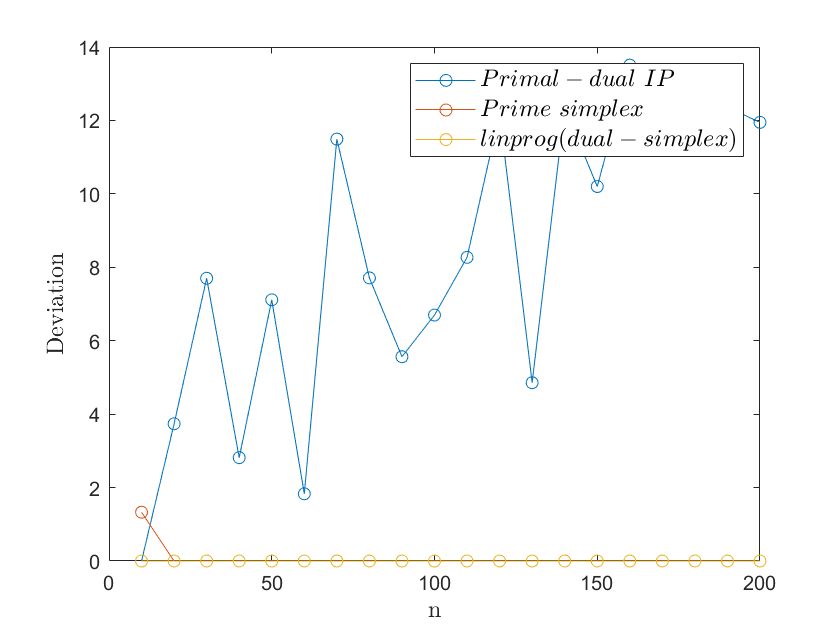

%Comparison of deviation of result and correct answer
t=10:10:200;
plot(t,niparray,'-o',t,nsimarray,'-o',t,nlinparray,'-o')
ylabel('Deviation','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Primal-dual \ IP$','$Prime\ simplex$','$linprog(dual-simplex)$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

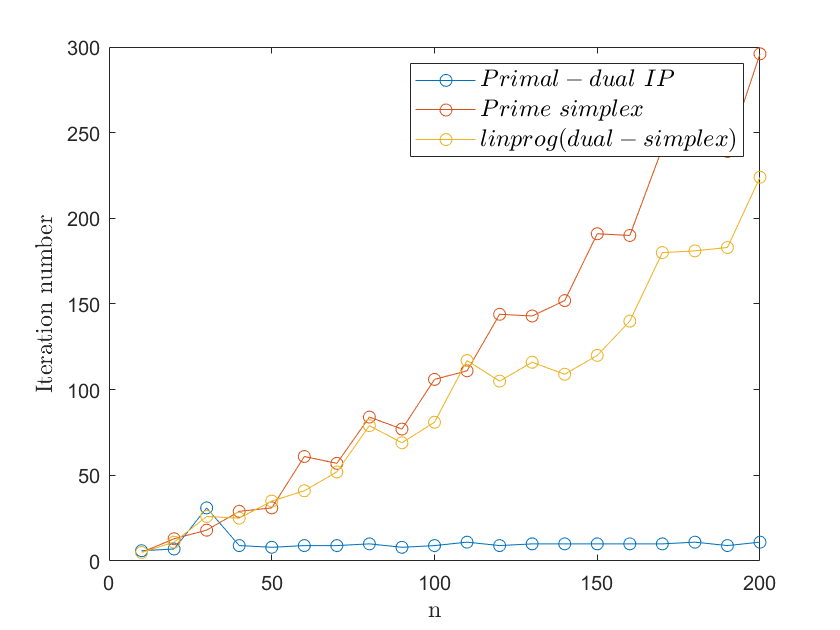

%Comparison of iteration
t=10:10:200;
plot(t,itip,'-o',t,itsim,'-o',t,itlinp,'-o')
ylabel('Iteration number','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Primal-dual \ IP$','$Prime\ simplex$','$linprog(dual-simplex)$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

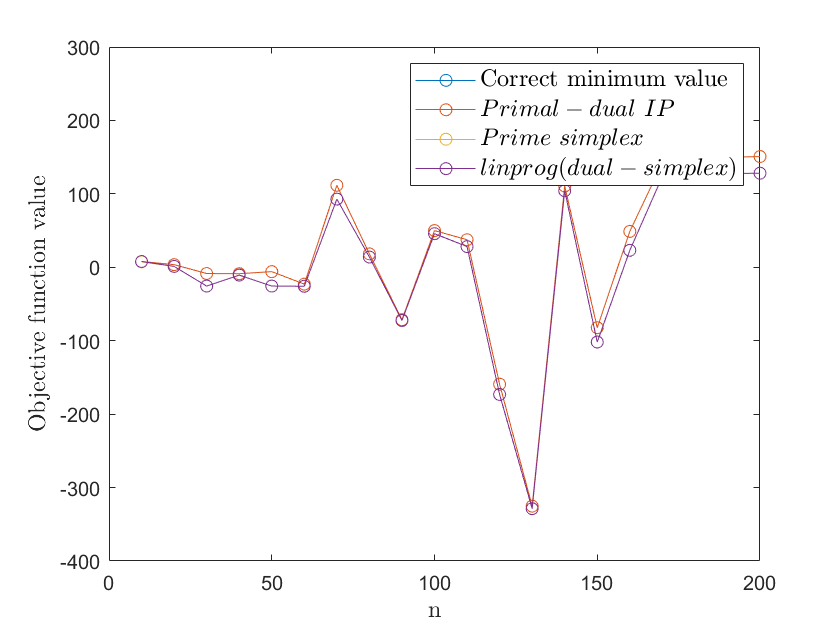

%Comparison of Objective function value
t=10:10:200;
plot(t,fvalgoal,'-o',t,fvaliparray,'-o',t,fvalsimarray,'-o',t,fvallinparray,'-o')
ylabel('Objective function value','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('Correct minimum value','$Primal-dual \ IP$','$Prime\ simplex$','$linprog(dual-simplex)$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%IP
t=10:10:200;
plot(t,niparray,'-o')
ylabel('Deviation','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Primal-dual \ IP$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%IP
t=10:10:200;
plot(t,fvalgoal,'-o',t,fvaliparray,'-o')
ylabel('Objective function value','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('Correct optimal solution','$Primal-dual \ IP$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%IP
t=10:10:200;
plot(t,itip,'-o')
ylabel('Iteration number','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Primal-dual \ IP$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%SIMPLEX
t=10:10:200;
plot(t,nsimarray,'-o')
ylabel('Deviation','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Prime simplex$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%SIMPLEX
t=10:10:200;
plot(t,fvalgoal,'-o',t,fvalsimarray,'-o')
ylabel('Objective function value','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('Correct optimal solution','$Prime simplex$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

%SIMPLEX
t=10:10:200;
plot(t,itsim,'-o')
ylabel('Iteration number','FontName','times','FontSize',12,'Interpreter','latex')
xlabel('n','FontName','times','FontSize',12,'Interpreter','latex')
leg1 = legend('$Prime simplex$');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex')

x_ip =     0.0000
    0.0000
    0.0000
    0.0000
    1.0000


output1 = 包含以下字段的 struct :
         fval: -17.6800
          lam: 0.7593
            s: [5×1 double]
    iteration: 4
       xarray: [5×5 double]


base = 1

x_sim =      0     0     0     0     1


output2 = 包含以下字段的 struct :
         case: 'found'
         fval: -17.6800
    iteration: 1
       xarray: [1 0 0 0 0]



Optimal solution found.



x_lin =      0
     0
     0
     0
     1


fvallinp = -17.6800

exitflag = 1

output3 = 包含以下字段的 struct :
         iterations: 0
    constrviolation: 0
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 0


lambda = 包含以下字段的 struct :
      lower: [5×1 double]
      upper: [5×1 double]
      eqlin: 17.6800
    ineqlin: []
